# Example of taking images from Zelux camera

#### Initialize Zelux camera and obtain the handles

[tlCameraSDK, tlCamera] = initializeZelux(exposure=0.0001, external_trigger=false);


******Zelux Initialization******

Dot NET assembly loaded.1 camera was discovered.
Setting up software/internal triggered image acquisition.


#### Take a single image

image = acquireZeluxImage(tlCamera);

Image frame number: 1


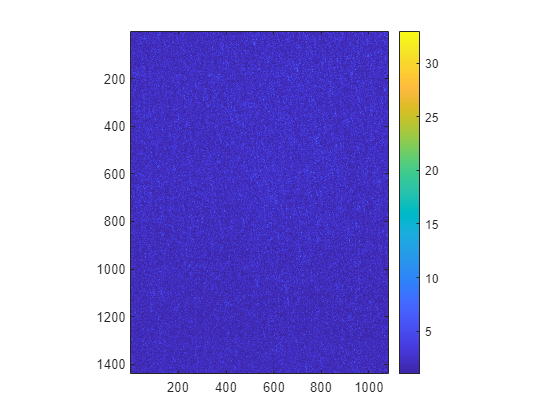

figure
imagesc(image)
daspect([1 1 1])
colorbar

#### Take a series of images with a loop

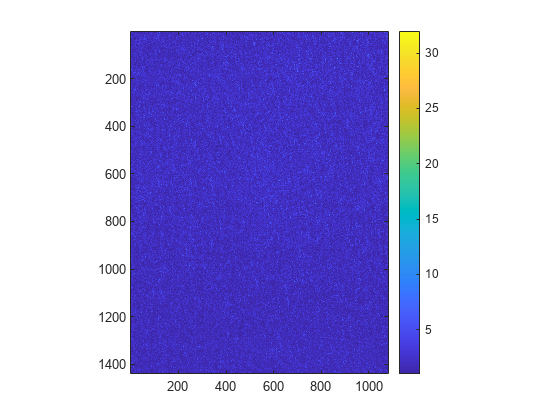

Image frame number: 2
Image frame number: 3
Image frame number: 4
Image frame number: 5
Image frame number: 6
Image frame number: 7
Image frame number: 8
Image frame number: 9
Image frame number: 10
Image frame number: 11


num_image = 0;
max_image = 10;

fig = figure;
while num_image < max_image
    
    image = acquireZeluxImage(tlCamera);
    num_image = num_image + 1;
    
    figure(fig)
    imagesc(image)
    daspect([1 1 1])
    colorbar

    drawnow
end

#### Close Zelux and release handles (necessary)

closeZelux(tlCameraSDK, tlCamera)


******Close Zelux******

Stopping image acquisition.
Releasing the camera
